# GMM

clear;clc;
X_train = load('CSE575-HW03-Data.csv');

gauss = @(x,mu,sigma) (1/((2*pi)^size(x,1)*det(sigma))^0.5)*exp(-0.5*(x-mu)'*(sigma\(x-mu)));

## Data Preparation

D = size(X_train,2);
K = 2;
% mu sigma are the initial means for GMM, assigned with the K means returned by K-means clustering implemented in Problem 2
load('mu_init_gmm.mat')
load('sigma_init_gmm.mat')
load('pi_k_init_gmm.mat')
gznk = gamma_znk(X_train,pi_k,mu,sigma,gauss);
N_k = sum(gznk,1)';

## EM Algorithm

LL = log_liklihood(X_train,pi_k,mu,sigma,gauss);
while(LL > 1e-5)
    for k=1:K
        temp_m = 0;        
        for i=1:size(X_train,1)
            temp_m = temp_m + gznk(i,k) * X_train(i,:);
        end
        mu(k,:) = temp_m/N_k(k);
        temp_s = 0;
        for i=1:size(X_train,1)
            temp_s = temp_s + gznk(i,k) * (X_train(i,:)-mu(k,:))'*(X_train(i,:)-mu(k,:));
        end
        sigma(k,:,:) = temp_s/N_k(k);
    end
    gznk = gamma_znk(X_train,pi_k,mu,sigma,gauss);
    N_k = sum(gznk,1)';
    pi_k = N_k/sum(N_k);
    LL = log_liklihood(X_train,pi_k,mu,sigma,gauss);
%     disp(LL);
end

   3.9055e+03

   3.8989e+03

   3.8979e+03

   3.8973e+03

   3.8970e+03

   3.8968e+03

   3.8967e+03

   3.8966e+03

   3.8965e+03

   3.8963e+03

   3.8962e+03

   3.8961e+03

   3.8960e+03

   3.8950e+03

   3.8915e+03

   3.8905e+03

   3.8905e+03

   3.8904e+03

   3.8904e+03

   3.8903e+03

   3.8903e+03

   3.8903e+03

   3.8903e+03

   3.8903e+03

   3.8903e+03

   3.8903e+03

   3.8903e+03

   3.8903e+03

   3.8903e+03

   3.8903e+03

   3.8903e+03

   3.8903e+03

   3.8903e+03

   3.8903e+03

   3.8903e+03

   3.8903e+03

   3.8903e+03

   3.8903e+03

   3.8903e+03

   3.8903e+03

   3.8903e+03

   3.8903e+03

   3.8903e+03

   3.8903e+03

   3.8903e+03

   3.8903e+03

   3.8903e+03

   3.8903e+03

   3.8903e+03

   3.8903e+03

   3.8903e+03

   3.8903e+03

   3.8903e+03

   3.8903e+03

   3.8903e+03

   3.8903e+03

   3.8903e+03

   3.8903e+03

   3.8903e+03

   3.8903e+03

   3.8903e+03

   3.8903e+03

   3.8903e+03

   3.8903e+03

   3.8903e+03

   3.8903e+03

   3.8903e

## Plot

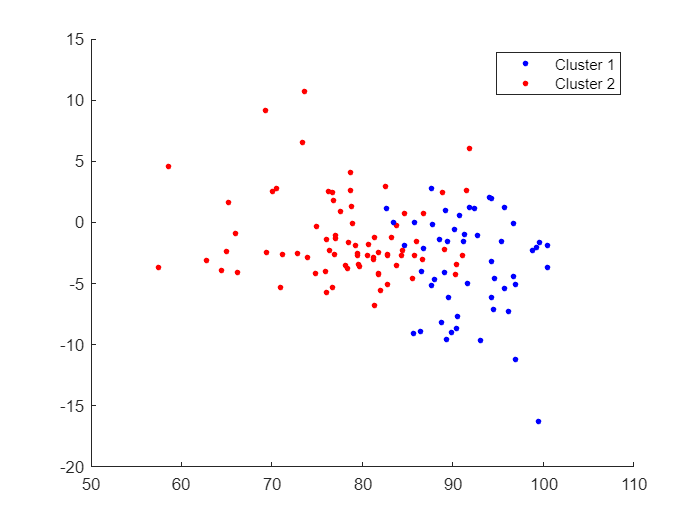

figure;
hold on;
for j=1:size(X_train,1)
    if gznk(j,1)>gznk(j,2)
        plot(X_train(j,1),X_train(j,2),'.','Color','blue','MarkerSize',10)
    else
        plot(X_train(j,1),X_train(j,2),'.','Color','red','MarkerSize',10)
    end
end
legend('Cluster 1', 'Cluster 2')
hold off;

function value = gamma_znk(X_train,pi_k,mu,sigma,fun)
    value = zeros(size(X_train,1),size(pi_k,1));
    for i=1:size(X_train,1)
        temp = 0;
        for k=1:size(pi_k,1)
            temp = temp + pi_k(k) * fun(X_train(i,:)',mu(k,:)',squeeze(sigma(k,:,:)));
        end
        for k=1:size(pi_k,1)
            value(i,k) = pi_k(k) * fun(X_train(i,:)',mu(k,:)',squeeze(sigma(k,:,:))) / temp;
        end
    end
end

function value = log_liklihood(X_train,pi_k,mu,sigma,fun)
    value = 0;
    for i=1:size(X_train,1)
        temp = 0;
        for k=1:size(pi_k,1)
            temp = temp + pi_k(k) * fun(X_train(i,:)',mu(k,:)',squeeze(sigma(k,:,:)));
        end
        value = value + log(temp);
    end
    value = -value;
end